# Scripts Fonctions de transfert

clear;clc;close all;
format shorteng; format compact;


Constantes

Kp = -1;


Définition de la fonction de transfert

num = [100];
den = [1, 2, 10, 0];
sys = tf(num, den)

sys =
 
         100
  ------------------
  s^3 + 2 s^2 + 10 s
 
Continuous-time transfer function.



Transformée inverse (besoin d'un addon "Inverse Laplace Transform of Transfer Function Class")

ilaplacetf(sys)

$$ans = 10-10\,{\mathrm{e}}^{-t}\,\left(\cos\left(3\,t\right)+\frac{\sin\left(3\,t\right)}{3}\right)$$

## Décomposer en fractions partielles

Utilisé pour faire Laplace inverse

... = r1/p1 + r2/p2 + r3/p3 + k

[r p k] = residue(num, den)

r =     -5.0000e+000 +  1.6667e+000i
    -5.0000e+000 -  1.6667e+000i
    10.0000e+000 +  0.0000e+000i


p =  -1000.0000e-003 +  3.0000e+000i
 -1000.0000e-003 -  3.0000e+000i
     0.0000e+000 +  0.0000e+000i


k =
     []


## Esquisser la réponse indicielle

à un saut unité

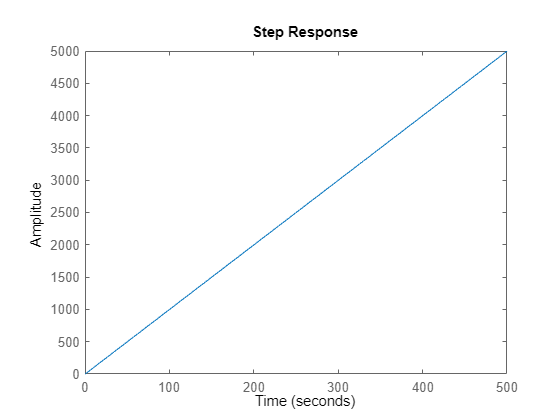

step(sys);

## Esquisser la réponse impulsionnelle

à une impulsion de dirac

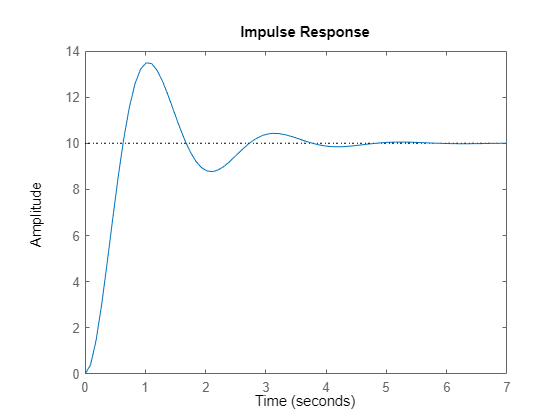

impulse(sys);

## Calculer les pôles

poles = pole(sys)

poles =      0.0000e+000 +  0.0000e+000i
 -1000.0000e-003 +  3.0000e+000i
 -1000.0000e-003 -  3.0000e+000i


## Pulsation naturelle

Si conjugués complexes

omega_0 = abs(poles(1)) % Norme

omega_0 =      0.0000e+000

Si non conjugués complexes

omega_0 = sqrt(poles(1) * poles(2))

omega_0 =      0.0000e+000

## Facteur d'amortissement

Si conjugués complexes

xi = - real(poles(1)) / omega_0

xi =              NaN

Si non conjugués complexes

xi = - (poles(1) + poles(2))/(2*omega_0)

xi =              Inf -             Infi

## Pulsation de résonnance

Si conjugués complexes

omega_r = abs(imag(poles(1)))

omega_r =      3.0000e+000

Si non conjugués complexes

omega_r = omega_0 * sqrt(1-xi^2)

omega_r =      0.0000e+000 +             NaNi

Constante de temps

tau = -1/(real(poles(1)))

tau =             -Inf